# Entomological Lidar Data Processing & Analysis Tutorial

## Created by Elizabeth M. Rehbein and Joseph A. Shaw

This tutorial has been created to familiarize the reader with the format of the data collected by the scanning entomological lidar and to guide them through basic data processing routines. The tutorial is written as a "MATLAB live script." This live script allows the user to work directly with data by running sections of pre-written code. Instruction is provided by use of written descriptions, figures, example datasets, and short sections of code. After completing this tutorial, the reader should have an understanding of how to manipulate the data and will have practiced identifying different types of signals such as those produced by insects, hard targets, and more. 

Questions about this tutorial can be addressed to elizabethrehbein@gmail.com. 

## **Lidar System Overview**

The goals of the scanning entomological lidar and the accompanying software are to collect data and isolate insect signals from noise and other non-insect signals for use in ecological studies. The design of the lidar system and data collection routines determine the format of the data collected, while processing routines enable an analyst to interpret the data. The insect lidar hardware consists of three primary components: the transmitting optics, receiving optics, and a moveable mount to which the optical components are fixed. The transmitting optics sit atop a Schmidt-Cassegrain telescope (12” Meade LX200 Classic) which acts as the receiver. The telescope is attached to a Moog QuickSet QPT-130 mount which can pan through 360 degrees and tilt through 180 degrees. The mount is bolted down to an optical breadboard for stability. See the image below for a visual of the lidar system [1]. Understanding the specific details of the transmitting optics is not necessary for pursuing the goals of this tutorial. For more information on the lidar system, [see Tauc et al. 2019](https://www.osapublishing.org/osac/fulltext.cfm?uri=osac-2-2-332&id=404411) [1]. 

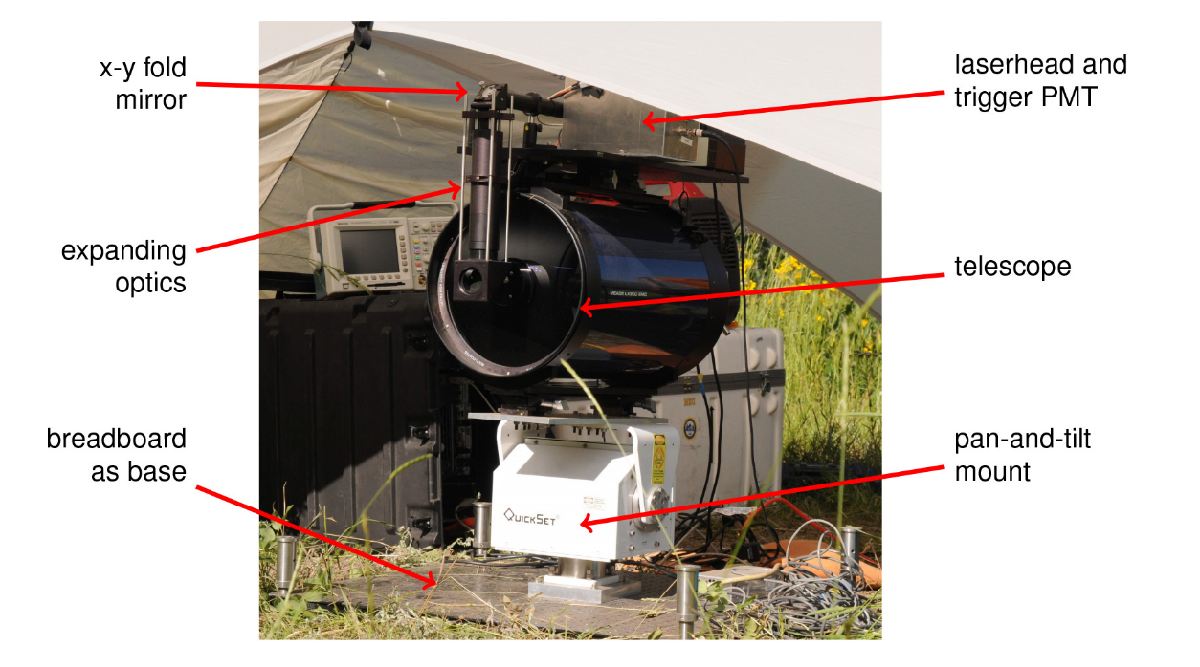

The essentials are as follows and are shown in the image below [1]. The laserhead produces pulsed light with a central wavelength of 532 nm which is then diverted and expanded to the center of the receiving telescope. The light exits the system, travels out into the study area, and any light that encounters an object is reflected back to the telescope where it is collimated to pass through a series of lenses and filters to a photomultiplier tube (PMT). The PMT converts the energy of the photons to a current which in turn is converted to a digital number by an analog to digital converter. A time series of digital numbers can then be interpreted to understand from what type of object the returned signal may have been created. The goal of the entomological lidar system is to determine the spatial distribution of insects throughout a conical volume of air during the day and night. To accomplish this, the mount steps

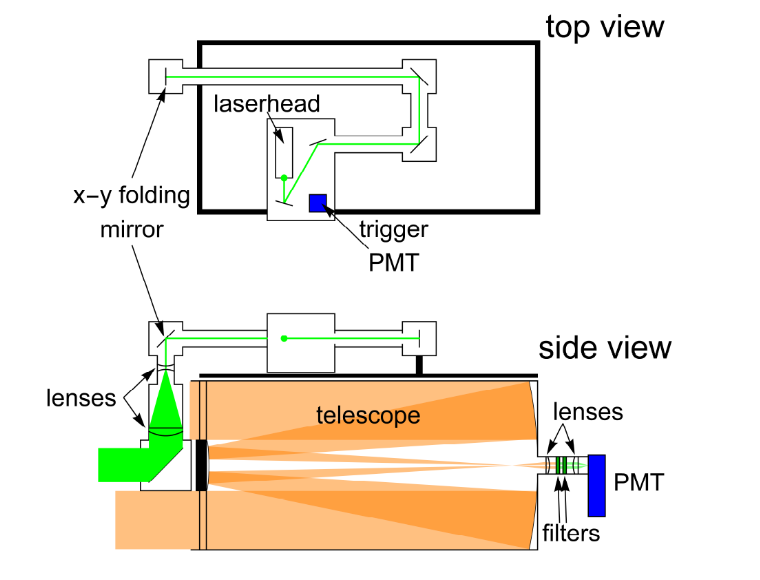

through a series of pan and tilt coordinates while the optical system transmits and collects data. The raw data collected are 1024 x 200 (time by range) arrays produced by sending out 1024 laser pulses at one pan/tilt location which are analyzed as a function of range. Each data point represents the signal return strength for a specific pulse number at a specific range. These data are saved in a MATLAB structure (a data type for storing and organizing data). From here, we move on to a more thorough discussion of the raw data, how it is processed, and then analyzed.

## **Post-Processing of  Raw Data**

Raw data are saved in 1024 x 200 arrays for every pan/tilt location to which the mount moves as it scans across a volume of air. Due to software limitations, only 178 of the original 200 range bins contain consistent usable data. The datasets provided in this tutorial are those that have been minimally processed using MATLAB scripts and include only usable data (1024 x 178 time/range arrays). These data represent the signal return strength from objects the pulsed light encounters. It is possible to identify insects and non-insect signals without any additional data processing, though additional processing may increase the analyst’s ability to recognize insect signatures. For simplicity’s sake, this tutorial will explore minimally processed data. We will identify the signatures created by stationary targets (also called hard targets), insects, and false insect signals (referred to as “ghost signals” in this document).

## Data Analysis: Overview

Detecting insects is relatively straightforward. The lidar system send out pulses of light, and when that light hits an object the light is reflected back to the lidar system where it is collected by a telescope. This backscattered light enables an analyst to identify from what type of object the light was reflected. This is done by considering the strength of the returned lidar signal as a function of time. The wing-beat modulation lidar developed by the Optical Remote Sensor Laboratory takes advantage of the fact that a flying insect will produce a signal that varies in time. A stationary object, like a tree, will produce a signal that is relatively constant in time. When laser light hits a flying insect's wing, that light is reflected back to the telescope and the system identifies that there is a signal. If that same insect then flaps its wings so that the laser light travels over the insect without hitting it, then the lidar system will not receive a signal back. The flapping wings of a flying insect return a modulated signal–on when the light hits the wings and off when the light misses the wings. This 

## 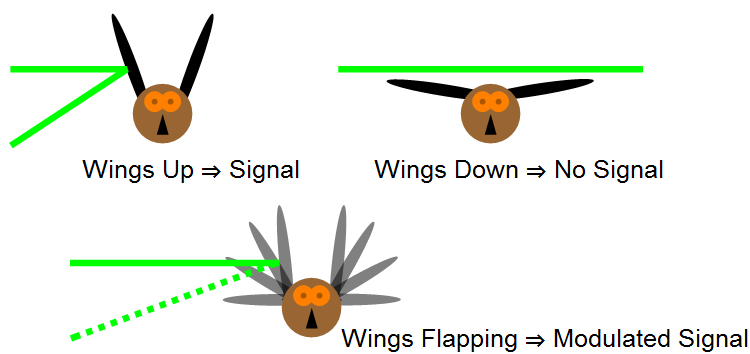

idea is modeled in the image above [2]. In contrast, empty air will return almost no signal while a solid object like a tree will return a strong signal that is relatively constant in time. When the signal return strength is plotted as a function of time, we can identify signals created by insects, empty air, moving vegetation, and hard targets like trees or rocks. See the image below for examples of what these various signals look like [2]. When we search for insects in the data, we are looking for signals that oscillate as a function of time. In the image below, the insect produces a signal that oscillates strongly, the empty air produces only noise, and the tree produces a high signal that varies in strength but does not appear to have a true oscillatory nature.

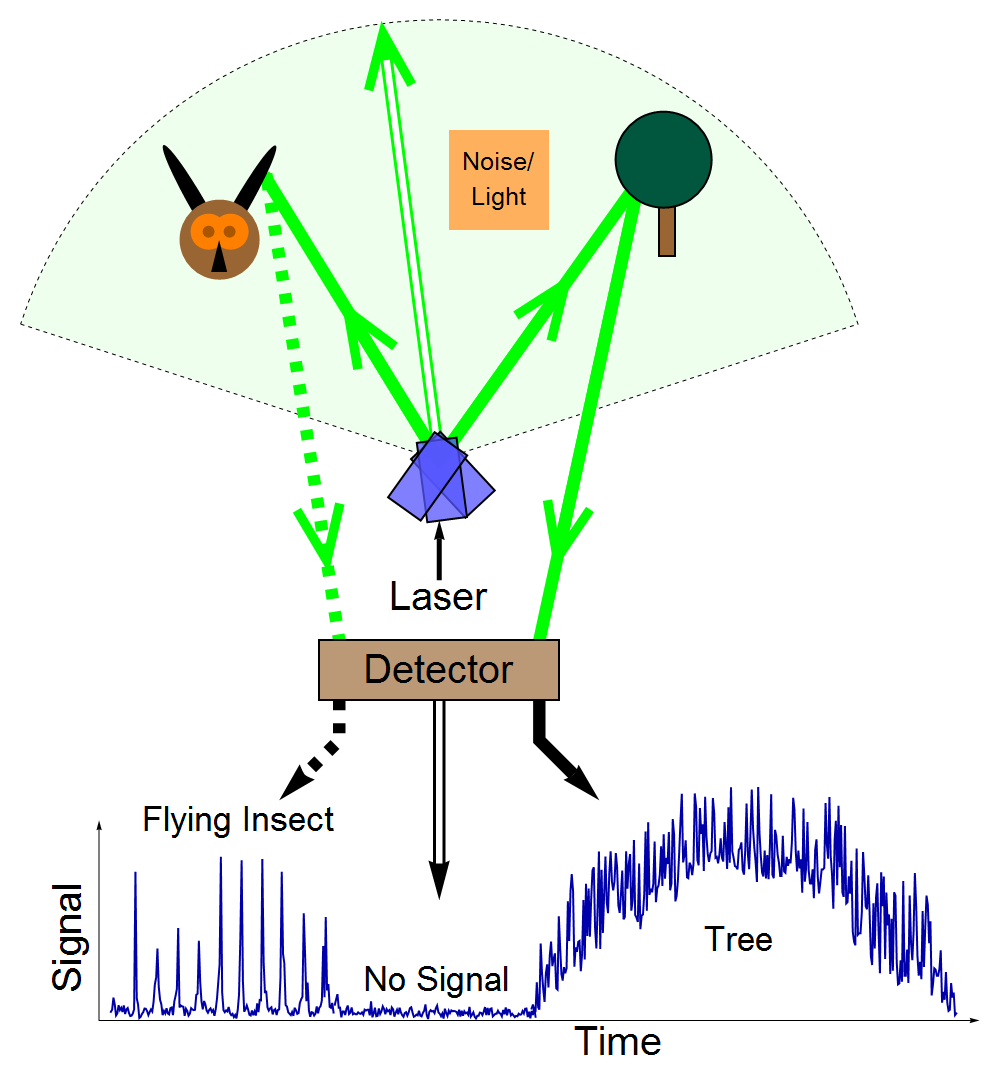

## **Data Analysis: Using Colormaps**

Let's dive in to some examples. In the section of code below, we use a built in MATLAB function called "imagesc" to visualize the data. The horizontal axis is the laser pulse number–you can think of this as "time." As pulse number increase, time increases, so the clock is moving forward in time. The vertical axis is range, or the distance away from the lidar. Each range bin represents 0.75 meters so that range bin "10" represents a space 7.5 meters away. There are 178 range bins of usable data, so the total range of the lidar system is about 133.5 meters. The different colors represent the strength of the return signal. This type of plot is called a colormap. In our case, the colormap shows us the strength of the return signal for every range bin as a function of time. 

Note: Run this section of code by clicking anywhere is the white block of texting surrounding the code, then select the "Run Section" button in the top portion of the MATLAB window. If you do not see this button, make sure the "LIVE EDITOR" tab is selected, as opposed to "HOME." 

Any text appearing after the percentage sign "%" is a comment and is used to explain what that line of code does.

imagesc(exampledata(1).data);       % Plot the first example

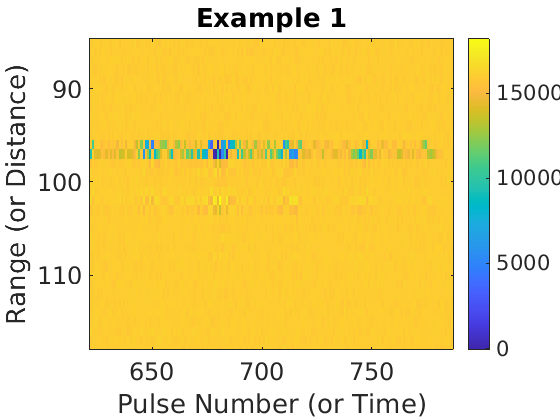

title('Example 1');                 % Add title
xlabel('Pulse Number (or Time)');   % Add x axis label
ylabel('Range (or Distance)');      % Add y axis label
colorbar;                           % Include the scale for the plot
set(gca,'FontSize',18);             % Use font size 18

As you can see above by examining the scale on the right hand side, the values in the colormap correspond to values between 0 and 18000. When the data are initially collected, their values, which correspond to the strength of the return signal, tend to be rather high. To simplify any additional processing or data visualization techniques we may utilize, we normalize the data. That is to say, we scale all the values in a 1024 x 178 array so that they are between 0 and 1. The strongest signal in that array will be set equal to 1 while the weakest return signal is set equal to 0. All intermediary values are adjusted accordingly. Let's look at the same example, but this time we will plot the normalized data and then try to figure out what we are seeing. Notice that if you ran the section of code above, the lines of code below have also been run and have produced the plot below.

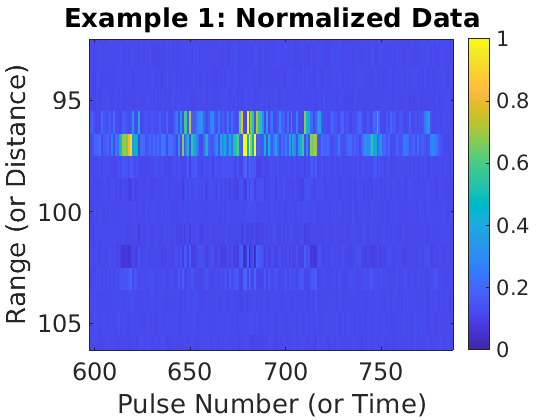

imagesc(exampledata(1).normalized_data);    % Plot the first example
title('Example 1: Normalized Data');        % Add title
xlabel('Pulse Number (or Time)');           % Add x axis label
ylabel('Range (or Distance)');              % Add y axis label
colorbar;                                   % Add the color scale for the data
set(gca,'FontSize',18);                     % Use font size 18

You have probably noticed that plots of these two colormaps look about the same–the colors may have changed, but the pattern is the same. This is exactly what we wanted. Normalizing the data just makes other data analysis techniques a bit easier. Now the returned signal strength varies between 0 and 1 instead of between 0 and 18,000. 

Now, what are you looking at? Recall the discussion above where we talked about the signals produced by different objects. The colormaps above certainly look different than the image above that demonstrated various signals, but the principals here are the same. For insects, we are looking for a signal that oscillates in time while hard targets (trees, rocks, etc.) produce signals that are relatively constant in time. In the colormap above, a large portion of the image is a darker blue which corresponds to a weak signal (dark blue has a value of "0," meaning no signal). In the figure below, we can examine these signals a little more closely. Range bins 150 through 165 exhibit rather persistent signals with high values near 1. Because these signals are relatively constant in time and have high return strengths, we identify them as hard targets. Given the study area for this data, these signals were likely produced by stationary objects such as trees. Ultimately, we are most interested in identifying insects. In the figure below, is a periodic signal around range bin 97 and maybe another near range bin 100. We will focus on the stronger signal in range bin 97. This signal is periodic (signal strength oscillates between higher and lower values), occurs over a small segment of time, and is stronger than the empty air signature. These are good indications that we are looking at a signal produced by an insect. There is also a return from range bin 100 that appears to be periodic and could easily be mistaken for another insect.

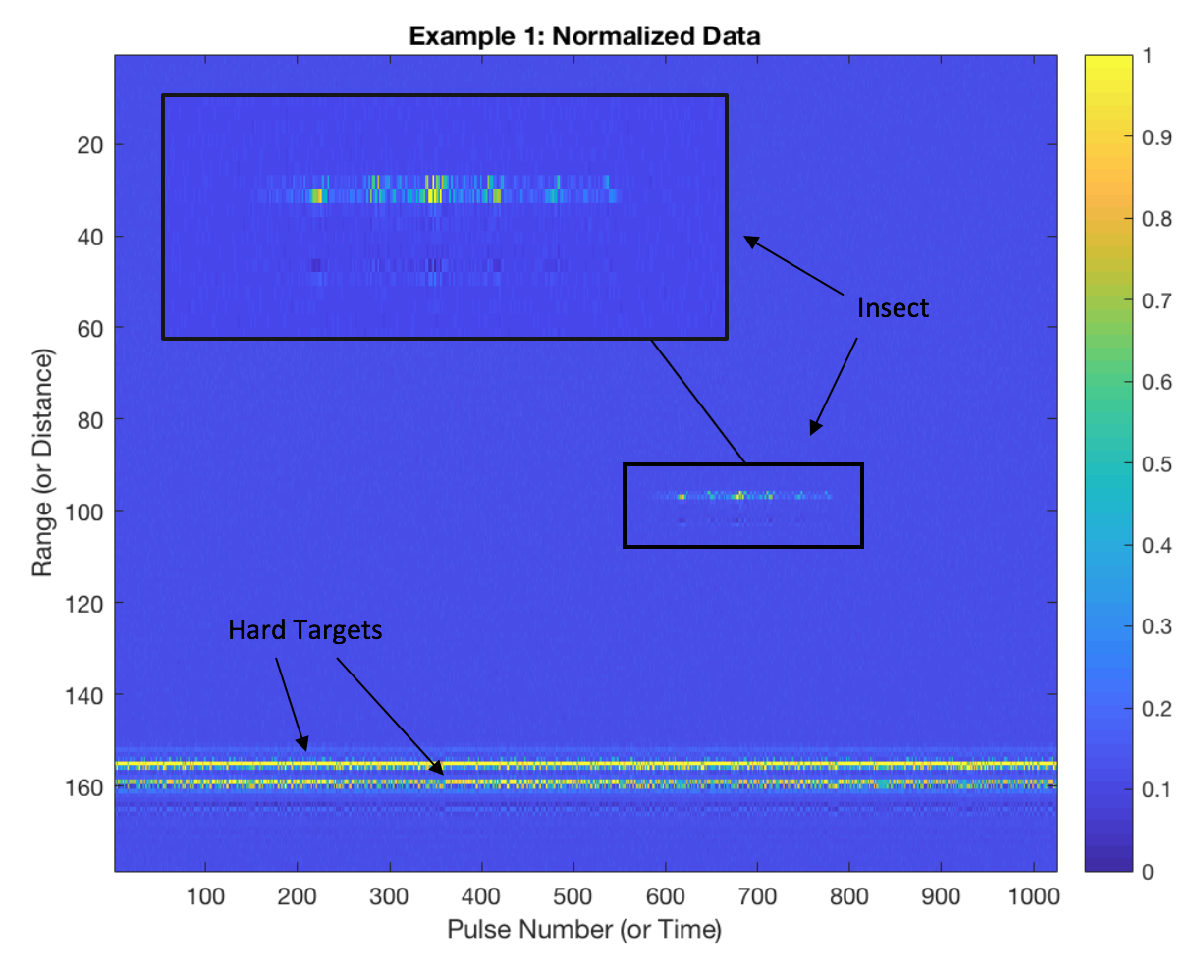

It has many of the same features as the other return we just identified as an insect, it is just weaker. These signals exist over roughly the same time period, pulses 580 through 790, which is a hint that we may not be seeing two separate insect detections. The weaker signal is actually not an insect at all, but a manifestation of the optical hardware that collects the returned light. The PMT is responsible for converting the energy of collected photons into a signal that can be read by the ADC. When a very strong signal hits the PMT, it can cause the PMT to output an oscillating signal. This signal is read by the ADC and is perceived as having been created by an insect at a different range bin than that from which the light was reflected back to the telescope. The signal we see in range bin 100 is a "ghost signal" that does not correspond to a physical insect present in the light beam at that distance. This type of phenomenon can occur from the light hitting a variety of objects such as insects, trees, and vegetation.

The example above contains almost all the phenomena that we are interested in being able to identify. However, it does not include an example of a slowly oscillating signal such as would be produced by vegetation moving in the wind or an insect with a rather slow wing beat. Run the code below (chanes are it has already been run) and look for the signal around range bin 109 that appears to vary in strength across pulse number. Notice that there seems to be a ghost signal from this object that appears in range bin 115 and that there is an insect signal in range bin 82. 

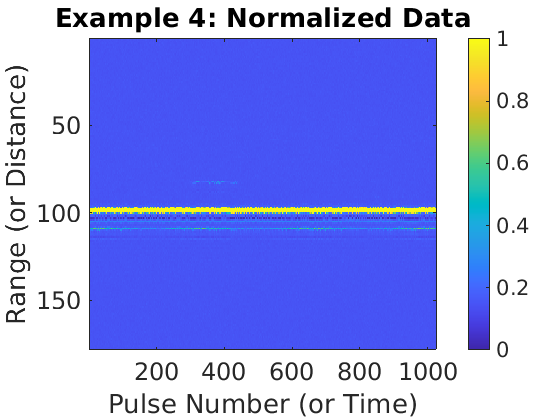

imagesc(exampledata(4).normalized_data);    % Plot the first example
title('Example 4: Normalized Data');        % Add title
xlabel('Pulse Number (or Time)');           % Add x axis label
ylabel('Range (or Distance)');              % Add y axis label
colorbar;                                   % Add the color scale for the data
set(gca,'FontSize',18);                     % Use font size 18

You can use this code to plot the other two examples that we haven't yet examined. To do this, simply replace the number "4" by the number "2" or "3." This will create colormaps for the data we haven't yet explored.

## **Data Analysis: Signals in the Time Domain**

So far we have looked at a number of signals produced by a variety of different objects and used colormaps to identify interesting signals. There are other tools we can leverage to dive further into our analysis of insect signals. Let's go back to example 1 to look at the insect signal in the time domain. Run the section of code below to produce a plot of the signal response with respect to time.

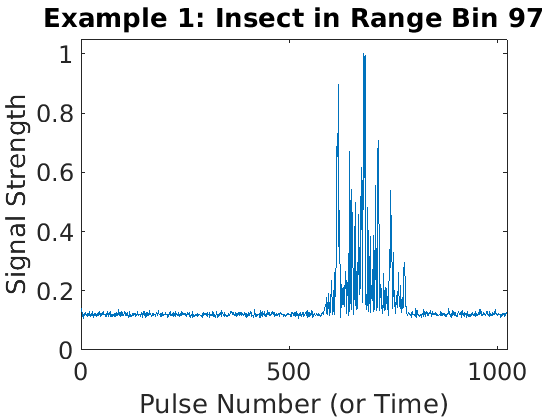

plot(exampledata(1).normalized_data(97,:));    % Plot the data from range bin 97 in the first example dataset
title('Example 1: Insect in Range Bin 97');    % Add title
xlabel('Pulse Number (or Time)');              % Add x axis label
ylabel('Signal Strength');                     % Add y axis label
xlim([0 1024]);                                % Set x axis limits
ylim([0 1.05]);                                % Set y axis limits
set(gca,'FontSize',18);                        % Use font size 18

In the plot above, notice that the signal strength is relatively low with the exception of pulses 575-783, during which the signal is much higher. Because the high return strength is present for a limited period of time, we can conclude that the object that caused this signal was only present in the light beam for a short period of time. We could expect this type of signal if an insect flew through the beam during a portion of the data collection period. A hard target such as a tree or slowly moving piece of vegetation would produce a signal that is distinctly different from that produced by an insect. The first section of code below plots a hard target from example dataset 1 in range bin 155 and the second section of code plots the slowly oscillating signal in range bin 109 from example dataset 4.

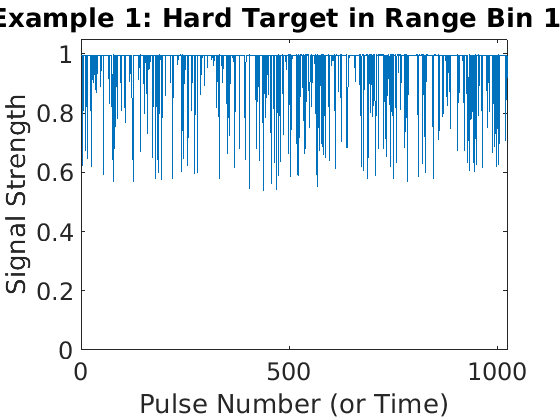

plot(exampledata(1).normalized_data(155,:));        % Plot the data from range bin 155 in the first example dataset
title('Example 1: Hard Target in Range Bin 155');   % Add title
xlabel('Pulse Number (or Time)');                   % Add x axis label
ylabel('Signal Strength');                          % Add y axis label
xlim([0 1024]);                                     % Set x axis limits
ylim([0 1.05]);                                     % Set y axis limits
set(gca,'FontSize',18);                             % Use font size 18

The plot above is of a hard target (given the experimental area, the hard target is most likely a tree) and has a rather consistent high signal strength that generally stays between the values 0.6 and 1.0. This makes sense given that the object is not moving through the beam path during this period of time. Additionally, a solid object such as a tree should return a large portion of the light that hits it, so the return strength is large. Next we plot the slowly oscillating signal.

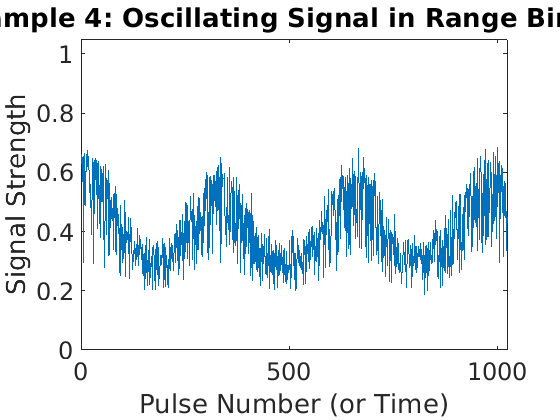

plot(exampledata(4).normalized_data(109,:));              % Plot the data from range bin 97 in the first example dataset
title('Example 4: Oscillating Signal in Range Bin 109');  % Add title
xlabel('Pulse Number (or Time)');                         % Add x axis label
ylabel('Signal Strength');                                % Add y axis label
xlim([0 1024]);                                           % Set x axis limits
ylim([0 1.05]);                                           % Set y axis limits
set(gca,'FontSize',18);                                   % Use font size 18

The plot above is a great example of a signal that varies in strength with time, but might vary too slowly to be caused by an insect. It is possible that this signal may have been caused by a piece of vegetation fluttering in the wind. We can examine this idea in more detail when we explore the frequency domain, which we will do next. 

## **Data Analysis:  Signals in the Frequency Domain**

While looking at return signals in the time domain can suggest what type of object the light has interacted with, examining these returns in the frequency domain can give us a more definitive answer as to what we are examining. This is accomplished by performing a Fourier Transform, which is a mathematical process in which a signal that is a function of time is converted to a signal that is a function of frequency. This process takes the original waveform (like those we examined in the section above) and decomposes it into sine and cosine waves of different frequencies. We can plot this new frequency information to determine the frequencies at which the original time signal was oscillating. For an insect signal, we can estimate the frequency at which an insect flaps its wings by looking for the fundamental frequency, which should be peak with the strongest amplitude and lowest frequency in the signal. We can check that the identified fundamental is in fact the perceived wing beat frequency by looking for harmonics. The harmonics occur in multiples of the fundamental. So, if the fundamental occurs at 100 Hz, we could expect to find harmonics at 200 Hz, 300 Hz, and so on. In reality, these harmonics may not occur in precise multiples of the fundamental due to imperfections in the lidar system.

Let's revisit the insect we found in example 1 in range bin 97. The code below will convert the time domain signal to the frequency domain so that the analyst can look for discernible harmonics indicative of an insect signal.  

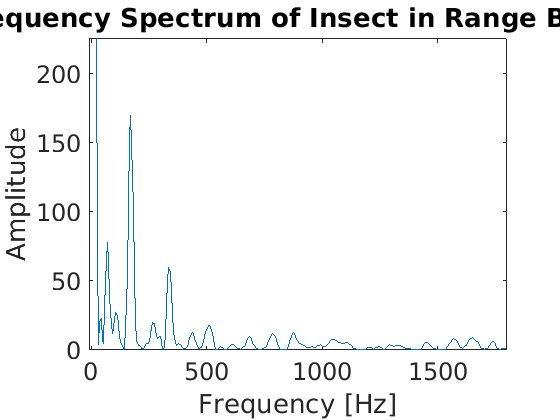

data=exampledata(1).normalized_data(97,:);              % Identify data of interest
nop=1024;                                               % Number of laser pulses per dataset
delta_f=1/(exampledata(1).time(end));                   % Frequency step size
fqdata=(-nop/2:nop/2-1).*delta_f;                       % Frequencies to use in plot
freq_signal=fftshift(fft(data(576:785),1024,2),2);      % Perform fourier transform on section of data
plot(fqdata,freq_signal.*conj(freq_signal));            % Plot the power spectral density (power/wavelength)
title('Frequency Spectrum of Insect in Range Bin 97');  % Add title
xlim([-10 1800]);                                       % Set limits for x axis
ylim([0 225]);                                          % Set limits for y axis
ylabel('Amplitude');                                    % Add y axis label
xlabel('Frequency [Hz]');                               % Add x axis label 
set(gca,'FontSize',18);                                 % Use font size 18

The plot generated by the code above displays the strength of the signal at each frequency. Ideally, the lowest frequency peak we see (not counting the one at 0 Hz) will be the fundamental frequency but we also know that the fundamental should be the strongest signal. The peak at 75 Hz is the lowest frequency but the peak at 170 Hz is the strongest so both are contenders for the fundamental. The simples way to determine which of these frequencies is the wing beat frequency is to look for harmonics of that frequency. We expect harmonics to follow at multiples of the fundamental, so if the fundamental is 170 Hz then the second harmonic should be near 340 Hz, the third around 510 Hz, and fourth near 680 Hz, and so on. This is exactly what we see in the plot above and I have indicated the locations of these harmonics in the image below. There are not easily discernible harmonics for 75 Hz, so this is not the fundamental frequency for the insect wing beat. The other peaks in this frequency spectrum could be due to a variety of phenomenon such as a nonsinusoidal wing beat, but because these other peaks do not produce easily discernible harmonics we are less interested in them.

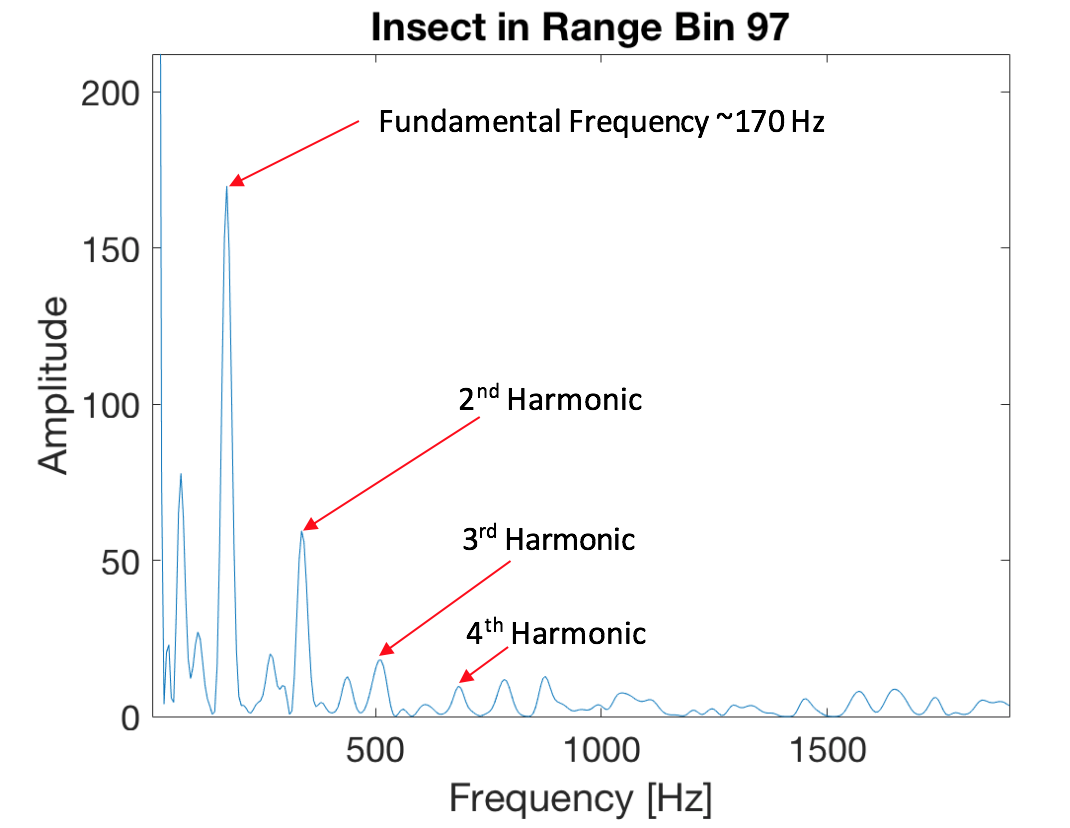

Now you have seen an example of what an insect signal looks like in the frequency domain. You can modify the code above to plot any range bin from any of the four example datasets. The insects are located in the data as follows: example 1: range 97, example 2: range 79, example 3: range 63, example 4: range 82. You may need to change the x or y axis limits to see the finer details in the plot. Do this by altering the values in the lines of code above for "xlim" and "ylim."

Insects are one of many possible objects with which the laser light may interact. Let's plot the frequency spectrums for the hard target and slowly oscillating signal that we looked at in the time domain. 

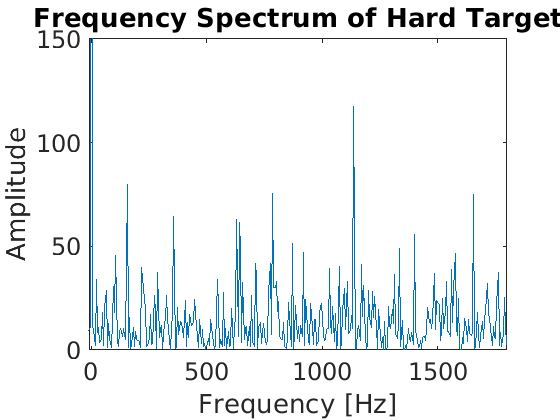

data=exampledata(1).normalized_data(155,:);             % Identify data of interest
nop=1024;                                               % Number of laser pulses per dataset
delta_f=1/(exampledata(1).time(end));                   % Frequency step size
fqdata=(-nop/2:nop/2-1).*delta_f;                       % Frequencies to use in plot
freq_signal=fftshift(fft(data(1:end),1024,2),2);        % Perform fourier transform on data
plot(fqdata,freq_signal.*conj(freq_signal));            % Plot the power spectral density (power/wavelength)
title('Frequency Spectrum of Hard Target');             % Add title
xlim([-10 1800]);                                       % Set limits for x axis
ylim([0 150]);                                          % Set limits for y axis
ylabel('Amplitude');                                    % Add y axis label
xlabel('Frequency [Hz]');                               % Add x axis label 
set(gca,'FontSize',18);                                 % Use font size 18

There are many peaks in the figure above but there does not appear to be a noticeably stronger low frequency peak indicative of a fundamental frequency. Most of the peaks have a relatively similar amplitude and there are no discernable harmonics present. This suggests the signal may have been produced by a stationary object. The next section of code plots the frequency spectrum for the slowly oscillating signal examined previously in the time domain. 

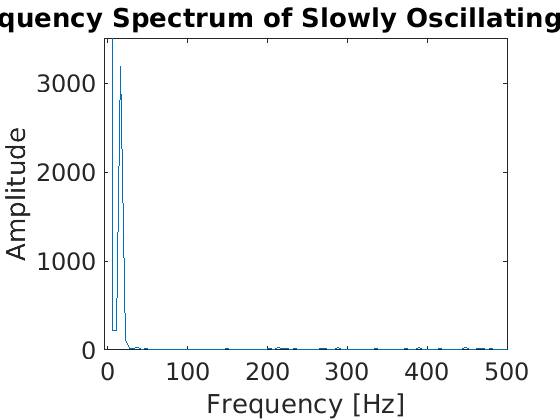

data=exampledata(4).normalized_data(109,:);                         % Identify data of interest
nop=1024;                                                           % Number of laser pulses per dataset
delta_f=1/(exampledata(1).time(end));                               % Frequency step size
fqdata=(-nop/2:nop/2-1).*delta_f;                                   % Frequencies to use in plot
freq_signal=fftshift(fft(data ,1024,2),2);                          % Perform fourier transform on section of data
plot(fqdata,freq_signal.*conj(freq_signal));                        % Plot the power spectral density (power/wavelength)
title('Frequency Spectrum of Slowly Oscillating Signal');           % Add title
xlim([-5 500]);                                                    % Set limits for x axis
ylim([0 3500]);                                                     % Set limits for y axis
ylabel('Amplitude');                                                % Add y axis label
xlabel('Frequency [Hz]');                                           % Add x axis label 
set(gca,'FontSize',18);                                             % Use font size 18

In the case of the oscillating signal, we see a very clear strong peak at a frequency of about 16 Hz. This peak is both the strongest in amplitude and the lowest in frequency so it is probably the fundamental frequency. The rest of the signal is very low in comparison to this peak so we will plot the data again with a smaller y axis limit so that we can see the finer details. 

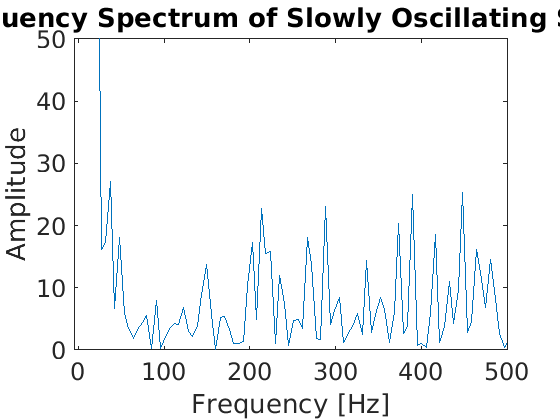

data=exampledata(4).normalized_data(109,:);                         % Identify data of interest
nop=1024;                                                           % Number of laser pulses per dataset
delta_f=1/(exampledata(1).time(end));                               % Frequency step size
fqdata=(-nop/2:nop/2-1).*delta_f;                                   % Frequencies to use in plot
freq_signal=fftshift(fft(data ,1024,2),2);                          % Perform fourier transform on section of data
plot(fqdata,freq_signal.*conj(freq_signal));                        % Plot the power spectral density (power/wavelength)
title('Frequency Spectrum of Slowly Oscillating Signal');           % Add title
xlim([-5 500]);                                                    % Set limits for x axis
ylim([0 50]);                                                       % Set limits for y axis
ylabel('Amplitude');                                                % Add y axis label
xlabel('Frequency [Hz]');                                           % Add x axis label 
set(gca,'FontSize',18);                                             % Use font size 18

If the fundamental frequency is 16 Hz, so we can expect harmonics around 32, 48, 64, and 80 Hz. This matches fairly well with the plot above where there are peaks at 37.4, 48.1, and 80.1 Hz, so it is likely that 16 Hz is in fact the fundamental. We do not see the 4th harmonic around 64 Hz, but this is not necessarily concerning given there are many variables influencing the signal collected by the telescope. Nonetheless, the frequency spectrum of this signal matches our initial impressions and helps confirm that this signal is oscillating rather slowly compared to the insect signal we examined earlier. It is possible that this signal could be caused by an insect with a lower wing beat frequency. 

Feel free to alter and change the code provided above. You can always access the original code by re-downloading the tutorial.

## Conclusion

This tutorial has provided an overview of the insect lidar system including the theory behind detecting insects with lidar and the hardware and software used to accomplish this. We have examined signals produced by insects, stationary objects, and slowly moving objects in both the time and frequency domains and learned what features to look for in these signals. We also considered how limits of the system, such as range resolution and ringing of the PMT, affect the data we collect and how we analyze them. Basic processing routines were discussed and demonstrated by use of code provided in this text. Each section of code can be altered to generate plots of different datasets and different range bins to enable the reader of this tutorial to examine and play with these data as curiosity prompts (note that the titles displayed on the figures may not be accurate when different data are plotted). The user of this tutorial should feel more comfortable with the format of the data generated by the insect lidar, how the data are processed and analyzed, and what various signals look like in the time and frequency domains. This tutorial is specific to the insect lidar system designed by the Optical Remote Sensor Laboratory at Montana State University. Basic lidar principles and the methods used to detect insects and other objects may be applicable to an insect lidar designed for use in an orchard setting. 

## References

[1] Martin Jan Tauc, Kurt M. Fristrup, Kevin S. Repasky, and Joseph A Shaw, "Field demonstration of a wing-beat modulation lidar for the 3D mapping of flying insects," OSA Continuum 2, 332-348 (2019)

[2] Martin Jan Tauc, Kurt M. Fristrup, Joseph A. Shaw, "Development of a wing-beat-modulation scanning lidar system for insect studies," Proc. SPIE 10406, Lidar Remote Sensing for Environmental Monitoring 2017, 104060G (30 August 2017);[ https://doi.org/10.1117/12.2274656](https://doi.org/10.1117/12.2274656) 